Lab 2 for Digital Audio Signal Processing Lab Sessions

Session 2: Binaural synthesis and 3D audio: OLA and WOLA frameworks R.Ali, G. Bernardi, J.Schott, A. Bertrand 2020

## Test OLA function: correctness

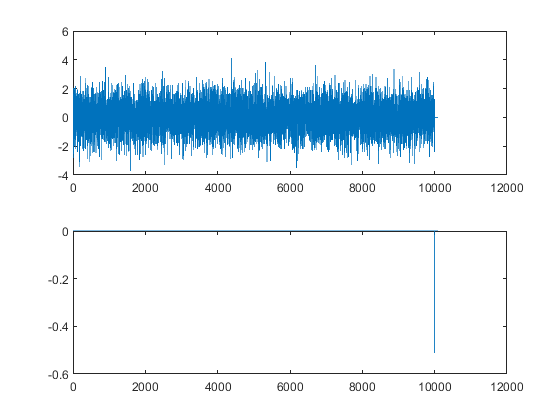

h = [1;zeros(99,1)];    % filter
x = randn(10000,1);     % signal
nfft = 512;             % num of fft points % nfft >= Lh + Lx -1;


y_OLA = OLA(x,h,nfft);

y_conv = conv(x,h);
% COMPARE
subplot(2,1,1);
plot(y_OLA);
subplot(2,1,2);
plot(y_conv);
err = y_conv - y_OLA;
plot(err);

## Test OLA function: speed

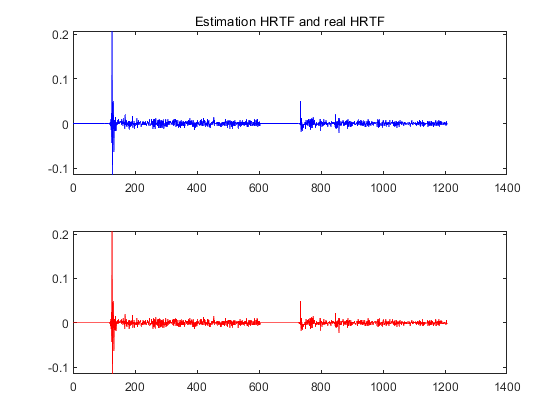

synth_error = 6.9730e-15

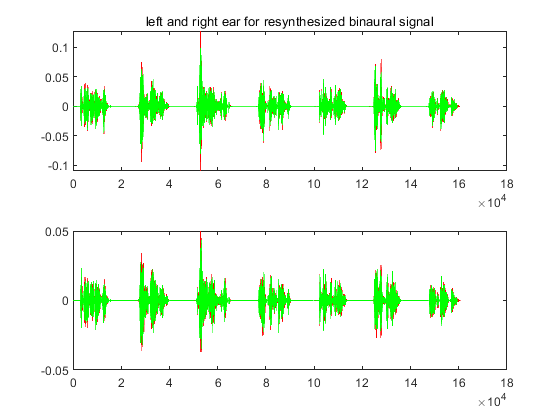

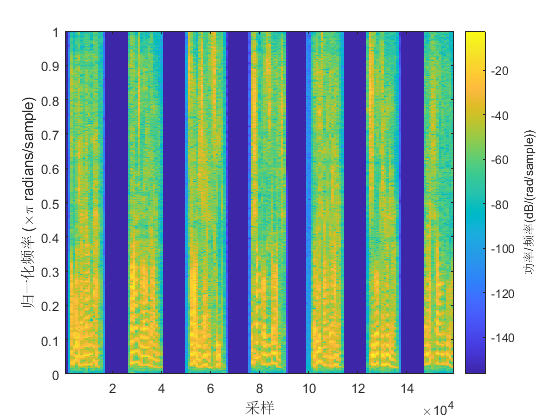

fftfilt: 0.20126
conv: 0.13826
OLA: 0.19031


run SOE_skeleton.mlx; disp("fftfilt: "+times(1));disp("conv: "+times(2));disp("OLA: "+times(3));